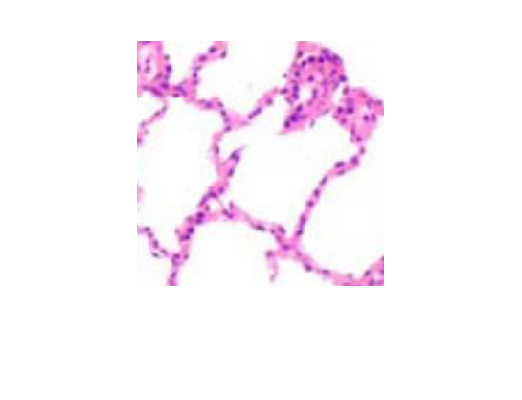

target_image_path = "C:\Users\bear\Desktop\figure 3\lung colour.png";
target_image = im2double(imread(target_image_path));
figure;
imshow(target_image);

folder = "C:\Users\bear\Desktop\figure 3";
filename = 'human lung_1';
outname = 'human lung_1_transformed';
extension = '.tif';
z = 68;
stack = import4d_big(folder, filename, extension, z, 3);

Finished importing channel 1
Finished importing channel 2
Finished importing channel 3


% only im2double works, double doesn't work...
plane = squeeze(stack(:,:,10,:));
disp(['Original type: ' class(plane)])

Original type: uint16


disp(['Original min: ' num2str(min(plane(:)))])

Original min: 12


disp(['Original max: ' num2str(max(plane(:)))])

Original max: 254



plane2 = im2double(plane) * 255;
disp(['Double type: ' class(plane2)])

Double type: double


disp(['Double min: ' num2str(min(plane2(:)))])

Double min: 0.046693


disp(['Double max: ' num2str(max(plane2(:)))])

Double max: 0.98833


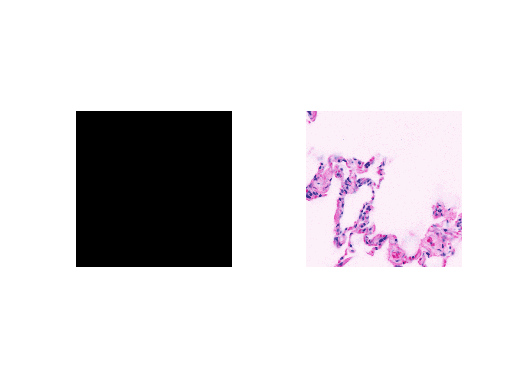


figure;
subplot(1,2,1); imshow(plane);
subplot(1,2,2); imshow(plane2);

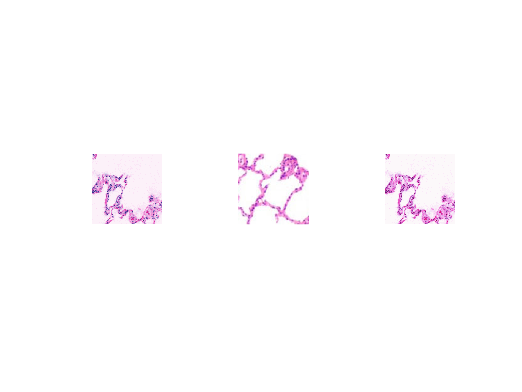

stack2 = im2double(stack) * 255;
transformed = zeros(size(stack2), 'like', stack2);
for i = 1:z
    transformed(:, :, i, :) = colour_transfer_MKL(squeeze(stack2(:, :, i, :)), target_image);
end
plane3 = squeeze(transformed(:,:,10,:));
figure;
subplot(1,3,1); imshow(plane2);
subplot(1,3,2); imshow(target_image);
subplot(1,3,3); imshow(plane3);

export4d(stack2, 3, folder, outname, extension);